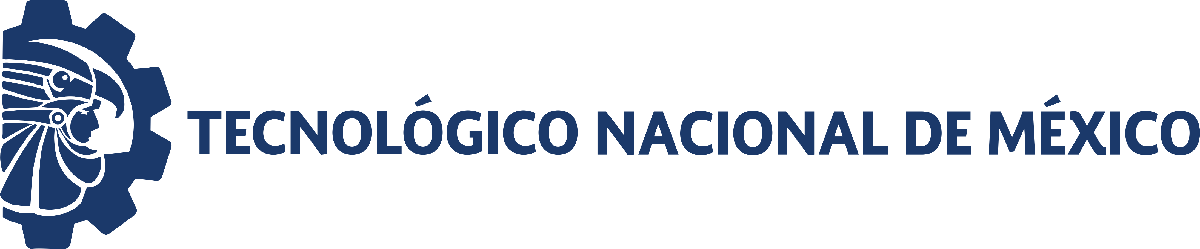                                 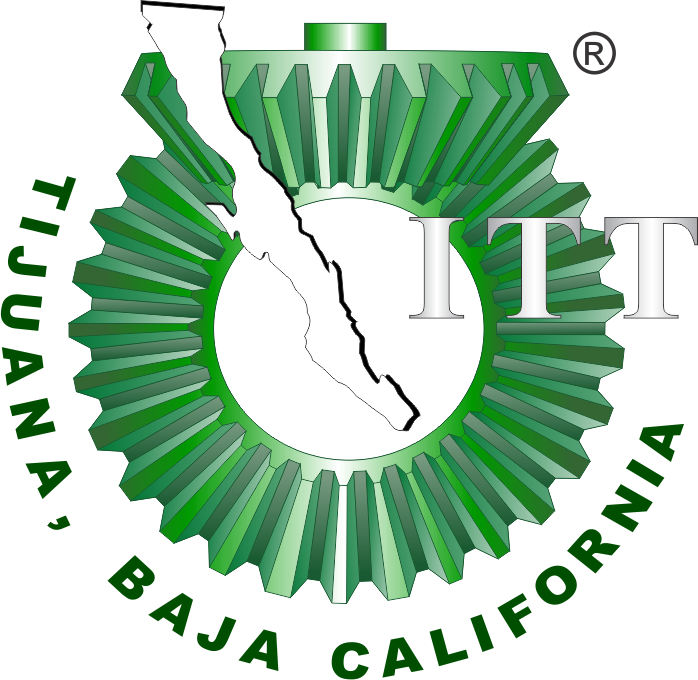

# Proyecto: Sistema Hepático

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

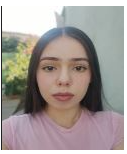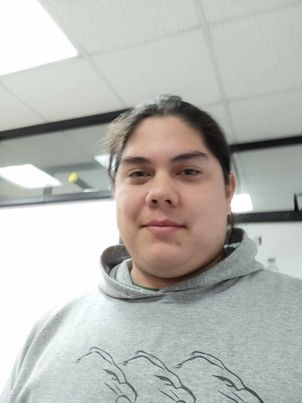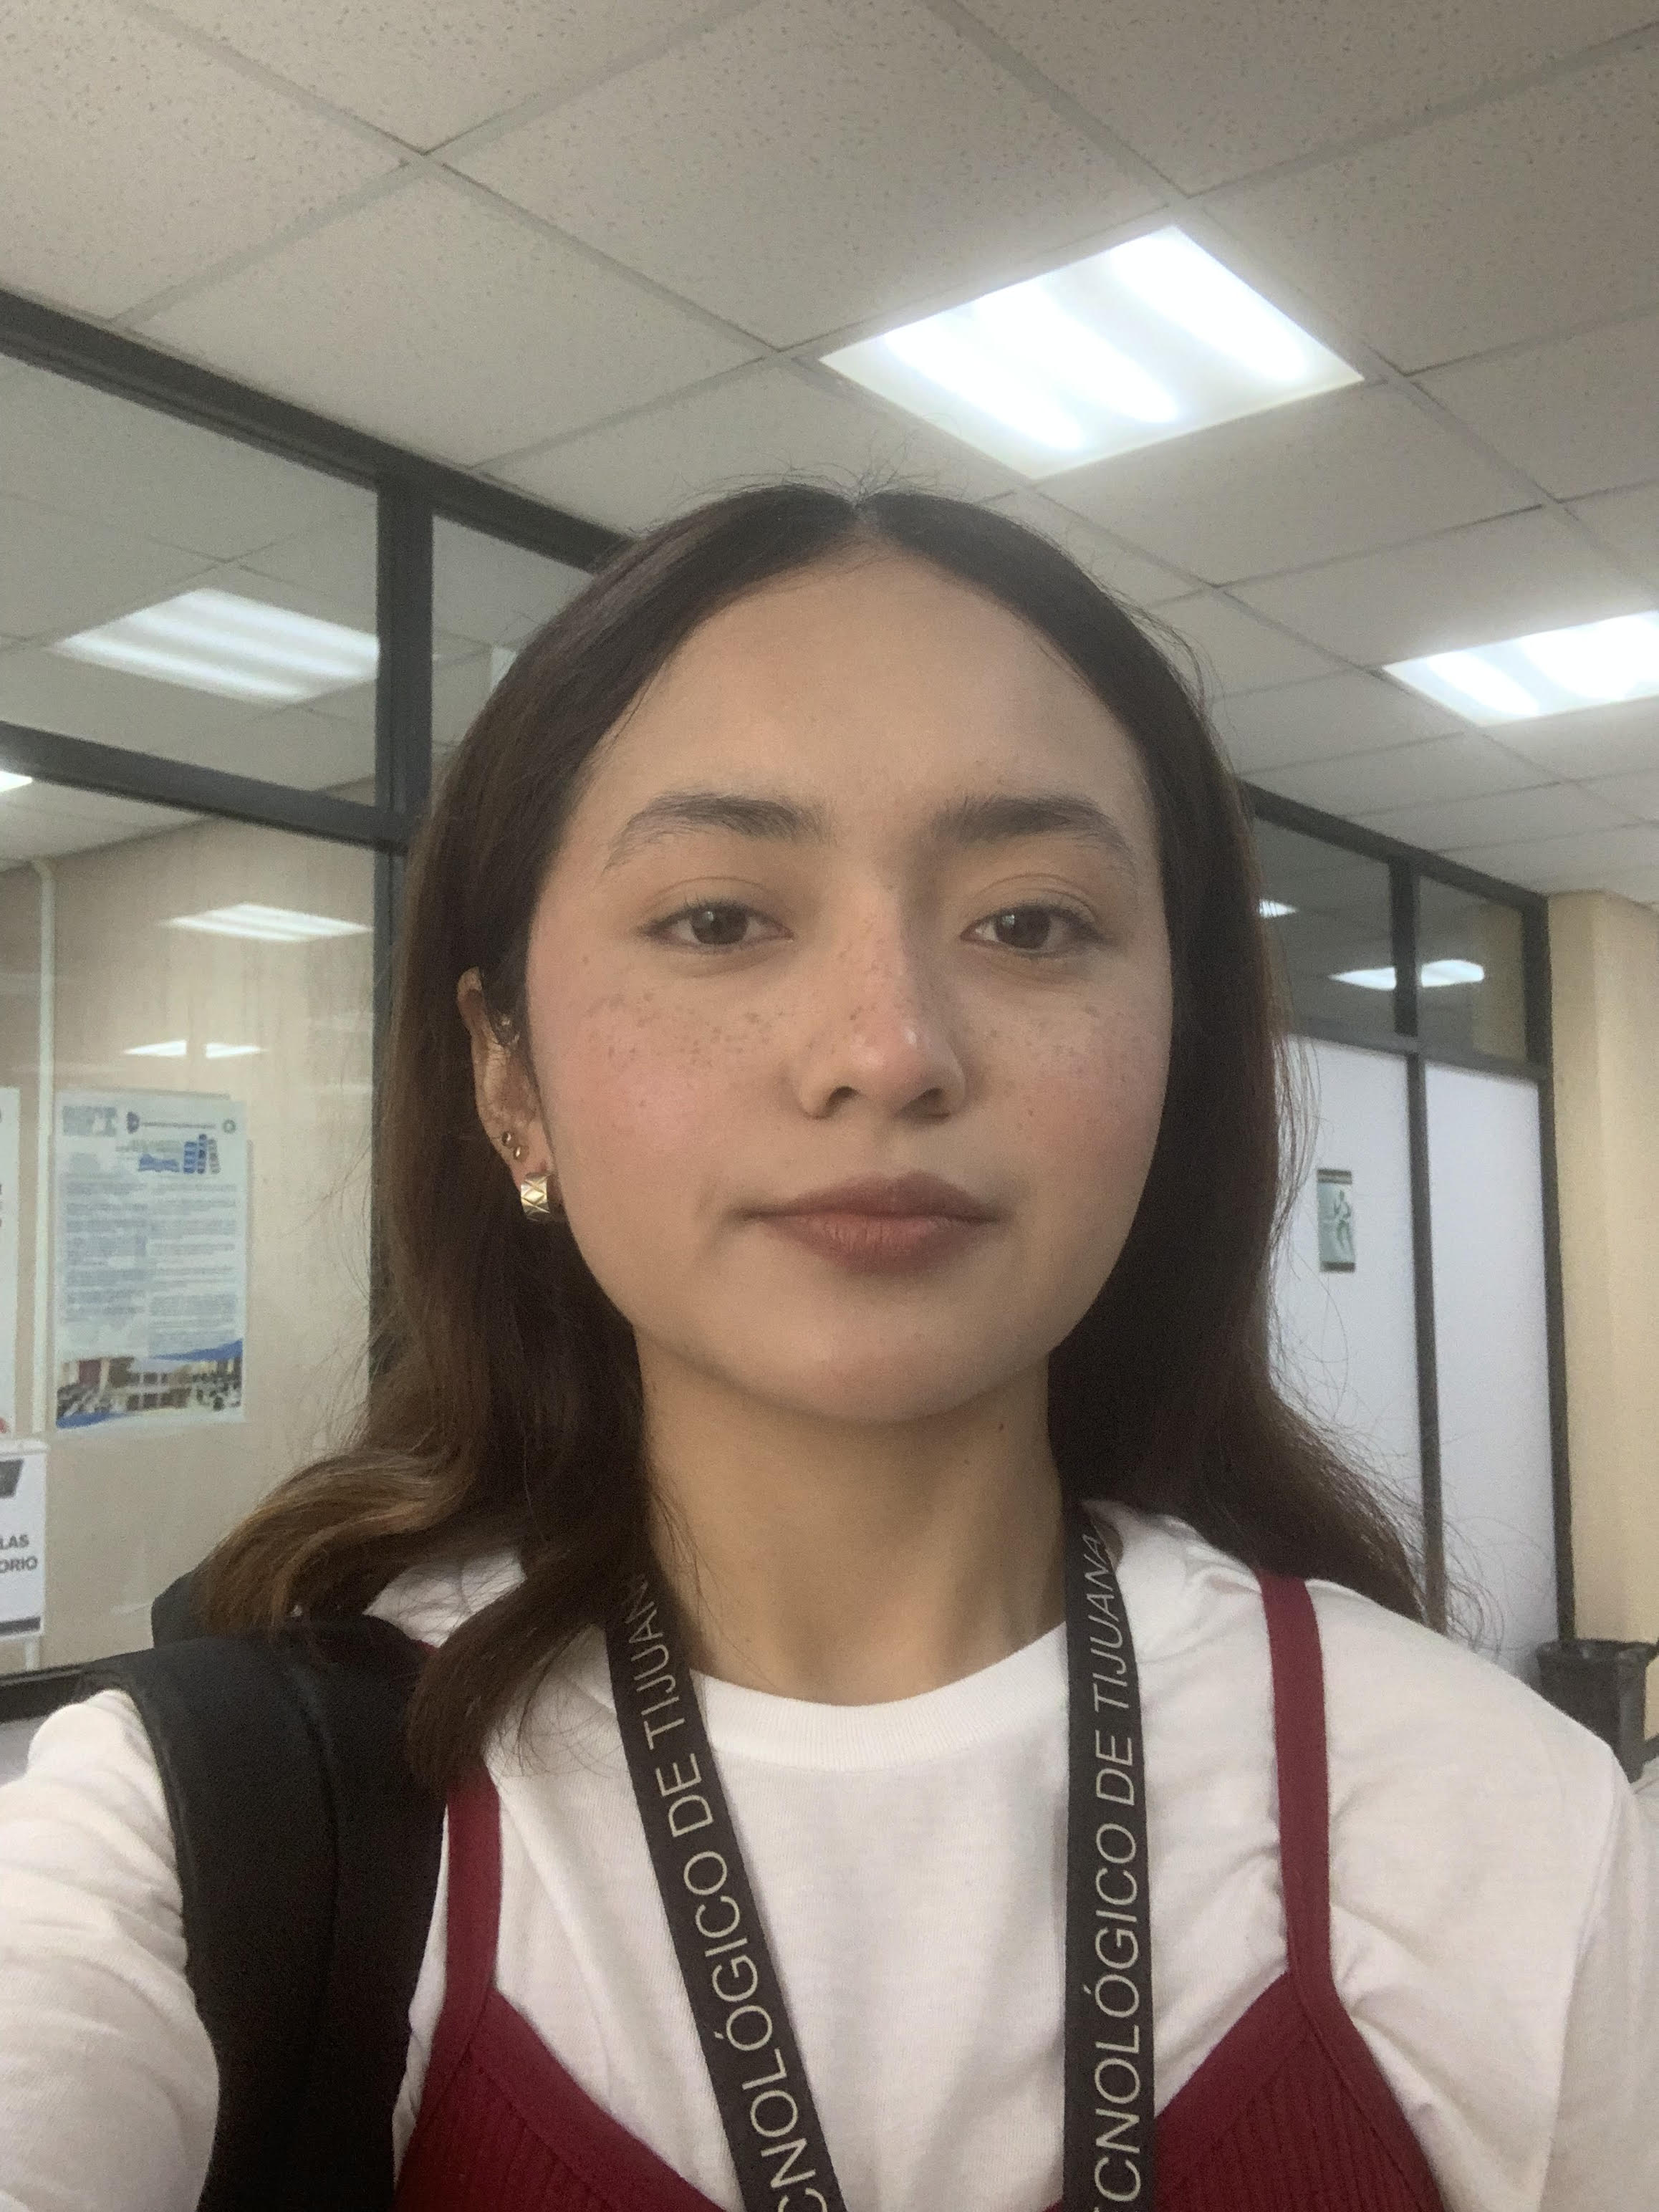

Nombre del alumno: **Beltrán Vega Sofía, Díaz Muruaga Carlos Manuel, Maldonado Delgado Lizette **

Número de control: **21212143, 21212741, 21212168**

Correo institucional: l**21212143@tectijuana.edu.mx, l21212741@tectijuana.edu.mx,  l21212168@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos generales de la simulación

clc; clear; close all;
tend='30';
open_system('Sistema');
parameters.Solver='ode23s';

## Parametros del controlador y rendimiento

## Respuesta a la función diente de sierra: Proceso metabolico en paciente sano

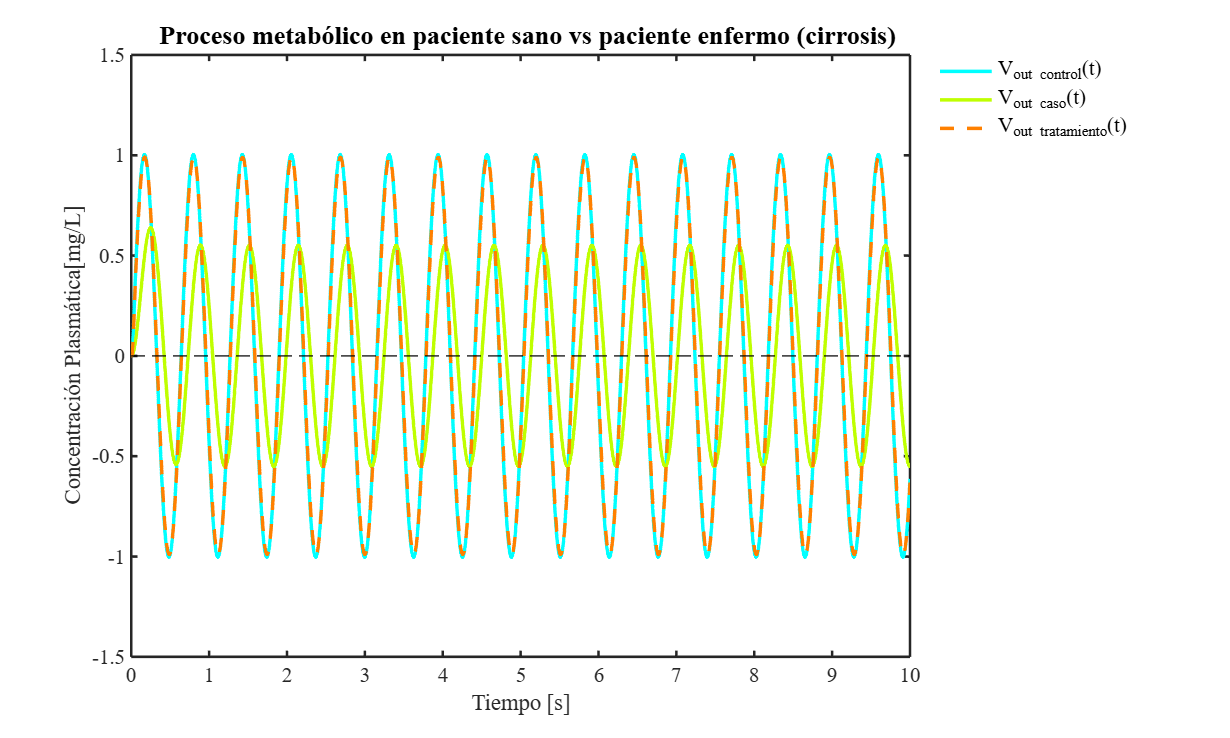

set_param('Sistema/Vin(t)', 'Amplitude','1');
set_param('Sistema/Vin(t)', 'Frequency','10');
set_param('Sistema/PID Controller', 'P', '12.082');
set_param('Sistema/PID Controller', 'I', '242.0391');
set_param('Sistema/PID Controller', 'D', '0.066498');
Signal='  Proceso metabólico en paciente sano vs paciente enfermo (cirrosis)';
N = sim('Sistema',parameters);
plotsignals(N.tout,N.Voutx,N.Vouty,N.Voutz,Signal)

## Funciones

function plotsignals(t, Voutx, Vouty,Voutz, Signal)
    figure('Color', 'w', 'Units', 'centimeters', 'Position', [3, 8, 25, 15]);
    ax = gca;
    set(ax, 'FontName', 'Times New Roman', 'FontSize', 12, ...
        'Box', 'on', 'LineWidth', 1.5, 'GridAlpha', 0.3, 'GridLineStyle', '--');
    hold on; grid off; box on
    colores = [
    1, 0, 1;     % Magenta para Pao
    0, 1, 1;     % Cian para PAx
    0.75, 1, 0;  % Verde limón para PAy
    1, 0.5, 0    % Naranja para PAz
    ];
  
   
   plot(t, Voutx, 'LineWidth', 2, 'Color', colores(2,:), 'DisplayName', 'V_{out control}(t)');
   plot(t, Vouty, 'LineWidth', 2, 'Color', colores(3,:), 'DisplayName', 'V_{out caso}(t)');
   plot(t, Voutz, 'LineStyle', '--', 'LineWidth', 2, 'Color', colores(4,:), 'DisplayName', 'V_{out tratamiento}(t)'); 

    L = legend('show');
    set(L, 'FontSize', 12, 'Location', 'northeastoutside', 'Box', 'off');
    title(Signal, 'FontSize', 15);
    xlabel('Tiempo [s]', 'FontSize', 13);
    ylabel('Concentración Plasmática[mg/L]', 'FontSize', 13);
    xlim([0, max(t)]);
    ylim([-1.5, 1.5]);
    xticks(0:1:max(t));
    yticks(-1.5:0.5:1.5);
    yline(0, '--k', 'LineWidth', 1, 'HandleVisibility', 'off');
    print(['S_' Signal '_.pdf'], '-dpdf', '-bestfit');
    exportgraphics(gcf,[Signal,'.png'],'Resolution','600')
    hold off;

end